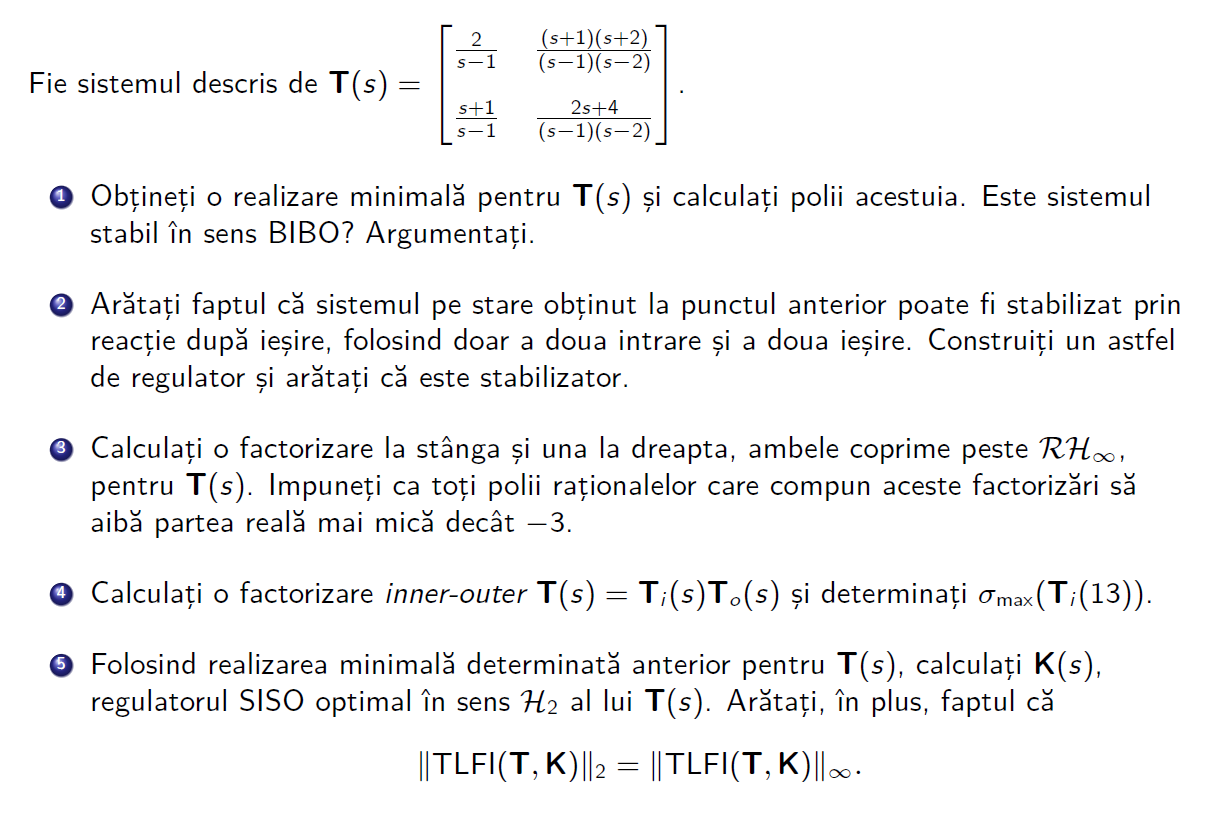

## Problema 1: realizare minimal si (in)stabil

clear
close all
clc

s = tf('s');
T = [2 / (s - 1), ((s + 1) * (s + 2) / ((s - 1) * (s - 2)));
     (s + 1) / (s - 1), (2*s + 4) / ((s - 1) * (s - 2))]


T =
 
  From input 1 to output...
         2
   1:  -----
       s - 1
 
       s + 1
   2:  -----
       s - 1
 
  From input 2 to output...
       s^2 + 3 s + 2
   1:  -------------
       s^2 - 3 s + 2
 
          2 s + 4
   2:  -------------
       s^2 - 3 s + 2
 
Continuous-time transfer function.



T_ss = ss(T,'min')


T_ss =
 
  A = 
           x1      x2
   x1   2.591  -1.591
   x2  0.5914  0.4086
 
  B = 
            u1       u2
   x1   0.9701    3.455
   x2   0.9701  -0.5448
 
  C = 
           x1      x2
   y1   1.781  0.2808
   y2  0.7808   1.281
 
  D = 
       u1  u2
   y1   0   1
   y2   1   0
 
Continuous-time state-space model.



disp('Este sistemul stabil?');

Este sistemul stabil?


disp(eig(T_ss.A)) % pot sa fac asta pentru ca am sitem minimal

     2
     1



disp(isstable(T_ss))

   0



Valorile proprii ale lui T_ss.A sunt din ${\mathbb{C}}^+$, deci instabile

Noi avem realizare minimala, deci inseamna ca sistemul este si controlabil si observabil

## Problema 2: Merge stabilizat de a doua intrare si a doua iesire

Scriu $T_{\mathrm{ss}} \;\mathrm{in}\;\mathrm{forma}\;\mathrm{de}\;\mathrm{matrice}\;\mathrm{sa}\;\mathrm{imi}\;\mathrm{fie}\;\mathrm{mai}\;\mathrm{simplu}$

T_ss


T_ss =
 
  A = 
           x1      x2
   x1   2.591  -1.591
   x2  0.5914  0.4086
 
  B = 
            u1       u2
   x1   0.9701    3.455
   x2   0.9701  -0.5448
 
  C = 
           x1      x2
   y1   1.781  0.2808
   y2  0.7808   1.281
 
  D = 
       u1  u2
   y1   0   1
   y2   1   0
 
Continuous-time state-space model.


T_mat_ss = [T_ss.A, T_ss.B;
            T_ss.C, T_ss.D]

T_mat_ss =     2.5914   -1.5914    0.9701    3.4552
    0.5914    0.4086    0.9701   -0.5448
    1.7808    0.2808         0    1.0000
    0.7808    1.2808    1.0000         0


Scriem $\left(A,B_2 ,C_2 ,D_2 \right)$

A2 = T_ss.A

A2 =     2.5914   -1.5914
    0.5914    0.4086



B2 = T_ss.B(:,2)

B2 =     3.4552
   -0.5448



C2 = T_ss.C(2,:)

C2 =     0.7808    1.2808



D2 = T_ss.D(2,2)

D2 = 0


T22 = ss(A2,B2,C2,D2)


T22 =
 
  A = 
           x1      x2
   x1   2.591  -1.591
   x2  0.5914  0.4086
 
  B = 
            u1
   x1    3.455
   x2  -0.5448
 
  C = 
           x1      x2
   y1  0.7808   1.281
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


Acum verific daca $\left\lbrace \begin{array}{l}
\left(A,B_2 \right)\mathrm{stabilizabil}\\
\left(C_2 ,A\right)\;\mathrm{detectabil}
\end{array}\right.$

Pc2 = ctrb(A2,B2)

Pc2 =     3.4552    9.8209
   -0.5448    1.8209



disp('Este sistemul controlabil?');

Este sistemul controlabil?


disp(rank(Pc2))

     2




Po2 = obsv(A2,C2)

Po2 =     0.7808    1.2808
    2.7808   -0.7192



disp('Este sistemul observabil?');

Este sistemul observabil?


disp(rank(Po2))

     2



Doamne ajuta, sistem minimal. Deci pot sa stabilizez sistemul T dupa $T_{22}$

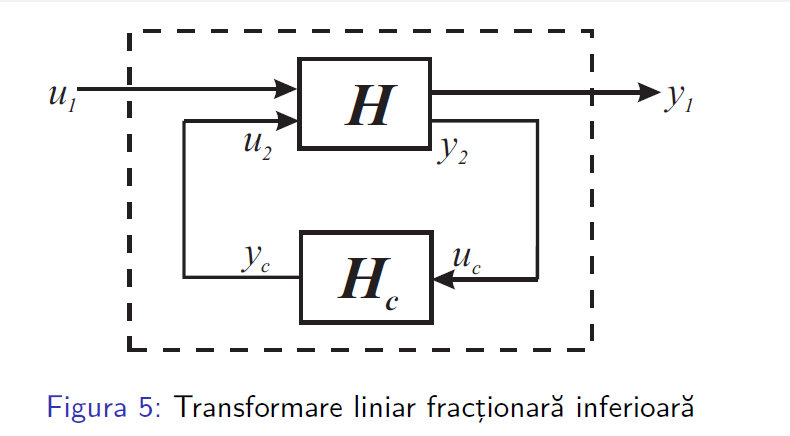

Hai sa vedem ca $T_{22}$ ia valorile instabile din T

disp('Valorile proprii din T_ss')

Valorile proprii din T_ss


eig(T_ss)

ans =      2
     1



disp('Valorile proprii din T22')

Valorile proprii din T22


eig(T22)

ans =      2
     1


Am luat K = -3 ca regulator pentru $T_{22}$

T(2,2)


ans =
 
     2 s + 4
  -------------
  s^2 - 3 s + 2
 
Continuous-time transfer function.



K = -3

K = -3


Kmatrix = [0 0;
           0 K];

Stab_22_cl = feedback(T(2,2), -K)


Stab_22_cl =
 
     2 s + 4
  --------------
  s^2 + 3 s + 14
 
Continuous-time transfer function.



disp(roots(Stab_22_cl.den{1}))

  -1.5000 + 3.4278i
  -1.5000 - 3.4278i




T_full_cl = feedback(T_ss, -Kmatrix);

disp('Polii sistemului complet in bucla inchisa:');

Polii sistemului complet in bucla inchisa:


disp(eig(T_full_cl.A));

  -1.5000 + 3.4278i
  -1.5000 - 3.4278i



Acum vad polii in bucla inchisa

polii_cl = pole(T_full_cl)

polii_cl =   -1.5000 + 3.4278i
  -1.5000 - 3.4278i



if all(real(polii_cl) < 0)
    disp(['Sistemul a fost stabilizat cu succes doar cu' ...
        ' intrarea 2 si iesirea 2']);
else
    disp('Sistemul NU este stabil.');
end

Sistemul a fost stabilizat cu succes doar cu intrarea 2 si iesirea 2


## Problema 3: factorizare coprima la stanga si dreapta

Am sistem minimal. In acest sens, fie $F\;\mathrm{si}\;L$ astfel incat $\left\lbrace \begin{array}{l}
\Lambda \left(A+\mathrm{BF}\right)\in {\mathbb{C}}_- \\
\Lambda \left(A+\mathrm{LC}\right)\in {\mathbb{C}}_- 
\end{array}\right.$. Atunci $\left\lbrace \begin{array}{l}
\left\lbrack \begin{array}{cc}
M & X\\
N & Y
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
A+\mathrm{BF} & B & -L\\
F & I & 0\\
C+\mathrm{DF} & 0 & I
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{cc}
\tilde{Y}  & -\tilde{X} \\
-\tilde{N}  & \tilde{M} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
A+\mathrm{LC} & -\left(B+\mathrm{LD}\right) & L\\
F & I & 0\\
C & -D & I
\end{array}\right\rbrack 
\end{array}\right.$

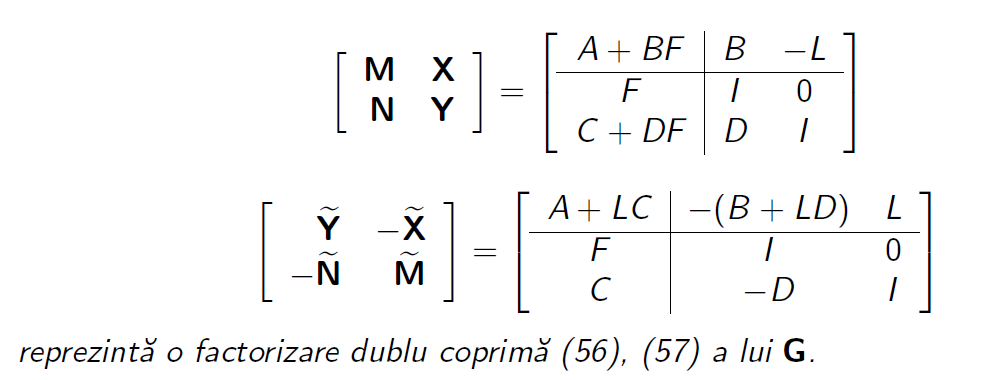

poli_dreapta = [-4 -5];
poli_stanga = [-5 -7];

F = -place(T_ss.A, T_ss.B, poli_stanga)

F =    -1.5923   -6.3731
   -1.7500    2.2500



L = -place(T_ss.A', T_ss.C', poli_dreapta)'

L =    -4.6977    2.2724
    1.6810   -4.5914


Sa verificam ca merge

disp('Valorile proprii ale lui A+BF');

Valorile proprii ale lui A+BF


disp(eig(T_ss.A + T_ss.B * F))

   -5.0000
   -7.0000




disp('Valorile proprii ale lui A+LC');

Valorile proprii ale lui A+LC


disp(eig(T_ss.A + L * T_ss.C));

   -4.0000
   -5.0000



Acum facem $M,N,\tilde{M} ,\tilde{N}$

NeTilda

M = ss(T_ss.A + T_ss.B * F, T_ss.B, F, eye(2,2))


M =
 
  A = 
               x1          x2
   x1          -5  -4.441e-16
   x2  -3.331e-16          -7
 
  B = 
            u1       u2
   x1   0.9701    3.455
   x2   0.9701  -0.5448
 
  C = 
           x1      x2
   y1  -1.592  -6.373
   y2   -1.75    2.25
 
  D = 
       u1  u2
   y1   1   0
   y2   0   1
 
Continuous-time state-space model.


N = ss(T_ss.A + T_ss.B * F, T_ss.B, T_ss.C + T_ss.D * F, T_ss.D)


N =
 
  A = 
               x1          x2
   x1          -5  -4.441e-16
   x2  -3.331e-16          -7
 
  B = 
            u1       u2
   x1   0.9701    3.455
   x2   0.9701  -0.5448
 
  C = 
            x1       x2
   y1  0.03078    2.531
   y2  -0.8116   -5.092
 
  D = 
       u1  u2
   y1   0   1
   y2   1   0
 
Continuous-time state-space model.


Tilda

Mtilde = ss(T_ss.A + L * T_ss.C, L, T_ss.C, eye(2,2))


Mtilde =
 
  A = 
               x1          x2
   x1          -4  -6.661e-16
   x2   4.441e-16          -5
 
  B = 
           u1      u2
   x1  -4.698   2.272
   x2   1.681  -4.591
 
  C = 
           x1      x2
   y1   1.781  0.2808
   y2  0.7808   1.281
 
  D = 
       u1  u2
   y1   1   0
   y2   0   1
 
Continuous-time state-space model.


Ntilde = ss(T_ss.A + L * T_ss.C, -(T_ss.B + L * T_ss.D), ...
    T_ss.C, -T_ss.D)


Ntilde =
 
  A = 
               x1          x2
   x1          -4  -6.661e-16
   x2   4.441e-16          -5
 
  B = 
           u1      u2
   x1  -3.243   1.243
   x2   3.621  -1.136
 
  C = 
           x1      x2
   y1   1.781  0.2808
   y2  0.7808   1.281
 
  D = 
       u1  u2
   y1   0  -1
   y2  -1   0
 
Continuous-time state-space model.



Ntilde = -Ntilde


Ntilde =
 
  A = 
               x1          x2
   x1          -4  -6.661e-16
   x2   4.441e-16          -5
 
  B = 
           u1      u2
   x1  -3.243   1.243
   x2   3.621  -1.136
 
  C = 
            x1       x2
   y1   -1.781  -0.2808
   y2  -0.7808   -1.281
 
  D = 
       u1  u2
   y1   0   1
   y2   1   0
 
Continuous-time state-space model.


Ma pot uita la $G*M-N$ si $\tilde{M} *G-\tilde{N}$ pentru a vedea daca chiar este coprima factorizarea $G={\mathrm{NM}}^{-1} ={\tilde{M} }^{-1} \tilde{\;N}$ 

disp('Ne uitam mai intai in partea dreapta')

Ne uitam mai intai in partea dreapta


norm(T_ss * M - N, 'inf')

ans = 7.9064e-16


disp('Acum sa vedem partea stanga')

Acum sa vedem partea stanga


norm(Mtilde * T_ss - Ntilde, 'inf')

ans = 4.7298e-16

## Problema 4: factorizarea inner-outer

Vrem $\left\lbrack \begin{array}{c}
N\\
M
\end{array}\right\rbrack =G_i G_o =\left\lbrack \begin{array}{c}
G_{\mathrm{i1}} \\
G_{\mathrm{i1}} 
\end{array}\right\rbrack G_o$

col_rf = [M;
          N]


col_rf =
 
  A = 
               x1          x2          x3          x4
   x1          -5  -4.441e-16           0           0
   x2  -3.331e-16          -7           0           0
   x3           0           0          -5  -4.441e-16
   x4           0           0  -3.331e-16          -7
 
  B = 
            u1       u2
   x1   0.9701    3.455
   x2   0.9701  -0.5448
   x3   0.9701    3.455
   x4   0.9701  -0.5448
 
  C = 
            x1       x2       x3       x4
   y1   -1.592   -6.373        0        0
   y2    -1.75     2.25        0        0
   y3        0        0  0.03078    2.531
   y4        0        0  -0.8116   -5.092
 
  D = 
       u1  u2
   y1   1   0
   y2   0   1
   y3   0   1
   y4   1   0
 
Continuous-time state-space model.


col_rf = ss(col_rf, 'min')


col_rf =
 
  A = 
               x1          x2
   x1          -5  -5.203e-16
   x2  -4.092e-16          -7
 
  B = 
            u1       u2
   x1    1.372    4.886
   x2    1.372  -0.7704
 
  C = 
            x1       x2
   y1   -1.126   -4.506
   y2   -1.237    1.591
   y3  0.02176     1.79
   y4  -0.5739   -3.601
 
  D = 
       u1  u2
   y1   1   0
   y2   0   1
   y3   0   1
   y4   1   0
 
Continuous-time state-space model.


rank(col_rf.D)

ans = 2

tzero(col_rf) %col_rf minimal, deci zero de invarianta = zero de transmisie


ans =

  0×1 empty double column vector



ACum vedem $\mathrm{EMAR}\left(\Sigma \right)$


$$\Sigma_{\mathrm{io}} :=\left(A;B;P\right)=\left(A;B;Q,L,R\right),\left\lbrack \begin{array}{cc}
Q & L\\
L^T  & R
\end{array}\right\rbrack =P=P^T$$


$Q=C^T C$, $L=C^T D$, $R=D^T D$

[X_r,F_r, spectru_r] = icare(col_rf.A, col_rf.B, col_rf.C'*col_rf.C, col_rf.D'*col_rf.D, col_rf.C'*col_rf.D)

X_r =     0.2192    0.0295
    0.0295    0.3785


F_r =    -0.6793   -3.7738
   -0.0837    1.6166


spectru_r =    -2.0000
   -2.2361


F_r = -F_r; % Facem reactie pozitiva, de-aia
H = chol(col_rf.D'*col_rf.D, 'lower')'

H =     1.4142         0
         0    1.4142


T_o = ss(col_rf.A, col_rf.B, -H*F_r, H)


T_o =
 
  A = 
               x1          x2
   x1          -5  -5.203e-16
   x2  -4.092e-16          -7
 
  B = 
            u1       u2
   x1    1.372    4.886
   x2    1.372  -0.7704
 
  C = 
            x1       x2
   y1  -0.9607   -5.337
   y2  -0.1183    2.286
 
  D = 
          u1     u2
   y1  1.414      0
   y2      0  1.414
 
Continuous-time state-space model.


Acum verific ca $T_o$ este outer

eig(T_o)

ans =    -5.0000
   -7.0000


eig(eye(size(T_o))/T_o) % fun fact: uita-te la spectru dupa icare:))))

ans =    -2.2361
   -2.0000


Acum pregatec partile pentru $G_{\mathrm{i1}} \;\mathrm{si}\;G_{\mathrm{i2}}$, mai specific $C_{\mathrm{r1}} ,C_{\mathrm{r2}} ,D_{\mathrm{r1}} ,D_{\mathrm{r2}}$

Ideea de baza: stim ca $G_i =\left\lbrack \begin{array}{cc}
A+\mathrm{BF} & {\mathrm{BH}}^{-1} \\
C+\mathrm{DF} & {\mathrm{DH}}^{-1} 
\end{array}\right\rbrack$. Insa noi am scris $G_i =\left\lbrack \begin{array}{c}
G_{\mathrm{i1}} \\
G_{12} 
\end{array}\right\rbrack$. A si B din $G_i$ nu ne afecteaza, ci C si D. Asadar, rescriem: $\left\lbrack \begin{array}{c}
G_{\mathrm{i1}} \\
G_{12} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
A+\mathrm{BF} & {\mathrm{BH}}^{-1} \\
C_1 +D_1 F & D_1 H^{-1} \\
C_2 +D_2 F & D_2 H^{-1} 
\end{array}\right\rbrack$

C_r1 = col_rf.C(1:2,:) 

C_r1 =    -1.1259   -4.5065
   -1.2374    1.5910


C_r2 = col_rf.C(3:4,:)

C_r2 =     0.0218    1.7895
   -0.5739   -3.6008


D_r1 = col_rf.D(1:2,:)

D_r1 =      1     0
     0     1


D_r2 = col_rf.D(3:4,:)

D_r2 =      0     1
     1     0


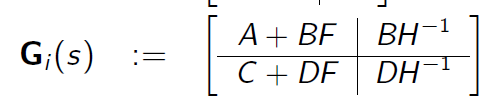

T_i1 = ss(col_rf.A + col_rf.B * F_r, col_rf.B * eye(size(H)) / H, C_r1 + D_r1 * F_r, D_r1 * eye(size(H)) / H)


T_i1 =
 
  A = 
            x1       x2
   x1   -3.659   -2.722
   x2   0.8675  -0.5769
 
  B = 
            u1       u2
   x1   0.9701    3.455
   x2   0.9701  -0.5448
 
  C = 
             x1        x2
   y1   -0.4467   -0.7327
   y2    -1.154  -0.02558
 
  D = 
           u1      u2
   y1  0.7071       0
   y2       0  0.7071
 
Continuous-time state-space model.


size(M) % Am atasat dimensiunile pentru a vedea de ce am luat pentru G_i1 si G_i2 C si D asa

State-space model with 2 outputs, 2 inputs, and 2 states.


size(T_i1)

State-space model with 2 outputs, 2 inputs, and 2 states.


T_i2 = ss(col_rf.A + col_rf.B * F_r, col_rf.B * eye(size(H)) / H, C_r2 + D_r2 * F_r, D_r2 * eye(size(H)) / H)


T_i2 =
 
  A = 
            x1       x2
   x1   -3.659   -2.722
   x2   0.8675  -0.5769
 
  B = 
            u1       u2
   x1   0.9701    3.455
   x2   0.9701  -0.5448
 
  C = 
           x1      x2
   y1  0.1054   0.173
   y2  0.1054   0.173
 
  D = 
           u1      u2
   y1       0  0.7071
   y2  0.7071       0
 
Continuous-time state-space model.


size(N)

State-space model with 2 outputs, 2 inputs, and 2 states.


size(T_i2)

State-space model with 2 outputs, 2 inputs, and 2 states.


Verificam daca este norma la dreapta (nu facem $G={\mathrm{NM}}^{-1}$, ci $\mathrm{GM}=N$)

norm(T_i2 - T * T_i1, 'inf')

ans = 3.9561e-15

cum verific ca $\left\lbrack \begin{array}{c}
\hat{M} \\
\hat{N} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
M\\
N
\end{array}\right\rbrack G_o =\left\lbrack \begin{array}{c}
G_{\mathrm{i1}} \\
G_{\mathrm{i2}} 
\end{array}\right\rbrack G_o$

norm(col_rf-[T_i1;T_i2]*T_o, 'inf')

ans = 5.5858e-16

Merge, acum vedem daca este si normalizata, adica ${\hat{M} }^{\tilde{} } \hat{M} +{\hat{N} }^{\tilde{} } \hat{N} =I$. Tot asa vedem ca am facut factorizarea inner ok

norm(T_i1'*T_i1 + T_i2'*T_i2 - eye(2), 'inf')

ans = 1.0069e-14

Acum scot factorul inner

[T_i1;
 T_i2]


ans =
 
  A = 
            x1       x2       x3       x4
   x1   -3.659   -2.722        0        0
   x2   0.8675  -0.5769        0        0
   x3        0        0   -3.659   -2.722
   x4        0        0   0.8675  -0.5769
 
  B = 
            u1       u2
   x1   0.9701    3.455
   x2   0.9701  -0.5448
   x3   0.9701    3.455
   x4   0.9701  -0.5448
 
  C = 
             x1        x2        x3        x4
   y1   -0.4467   -0.7327         0         0
   y2    -1.154  -0.02558         0         0
   y3         0         0    0.1054     0.173
   y4         0         0    0.1054     0.173
 
  D = 
           u1      u2
   y1  0.7071       0
   y2       0  0.7071
   y3       0  0.7071
   y4  0.7071       0
 
Continuous-time state-space model.


Ti = [T_i1;T_i2];
Ti = ss(Ti, 'min') % am facut pentru usurinta la calcul


Ti =
 
  A = 
           x1      x2
   x1  -3.156  -3.263
   x2  0.3258   -1.08
 
  B = 
           u1      u2
   x1   1.061    4.94
   x2   1.625  0.2506
 
  C = 
            x1       x2
   y1  -0.2026  -0.5719
   y2  -0.7947  -0.1854
   y3  0.04782    0.135
   y4  0.04782    0.135
 
  D = 
           u1      u2
   y1  0.7071       0
   y2       0  0.7071
   y3       0  0.7071
   y4  0.7071       0
 
Continuous-time state-space model.


Ti_tf = tf(Ti)


Ti_tf =
 
  From input 1 to output...
       0.7071 s^2 + 1.851 s + 0.874
   1:  ----------------------------
          s^2 + 4.236 s + 4.472
 
         -1.144 s + 2.288
   2:  ---------------------
       s^2 + 4.236 s + 4.472
 
         0.2701 s + 0.5402
   3:  ---------------------
       s^2 + 4.236 s + 4.472
 
       0.7071 s^2 + 3.265 s + 3.702
   4:  ----------------------------
          s^2 + 4.236 s + 4.472
 
  From input 2 to output...
         -1.144 s - 2.288
   1:  ---------------------
       s^2 + 4.236 s + 4.472
 
       0.7071 s^2 - 0.9772 s - 0.874
   2:  -----------------------------
           s^2 + 4.236 s + 4.472
 
       0.7071 s^2 + 3.265 s + 3.702
   3:  ----------------------------
          s^2 + 4.236 s + 4.472
 
         0.2701 s + 0.5402
   4:  ---------------------
       s^2 + 4.236 s + 4.472
 
Continuous-time transfer function.


Ti_13 = evalfr(Ti, 13) % ce face este sa vada valoare in s dat de mine

Ti_13 =     0.6320   -0.0751
   -0.0551    0.4635
    0.0177    0.7248
    0.7248    0.0177


DIn ce stiu, $\sigma_{\max }$ estre valoarea maxima singulara a MT $T_i \left(13\right)$

sigma_max = max(svd(Ti_13))

sigma_max = 0.9694

# **Un alt test**

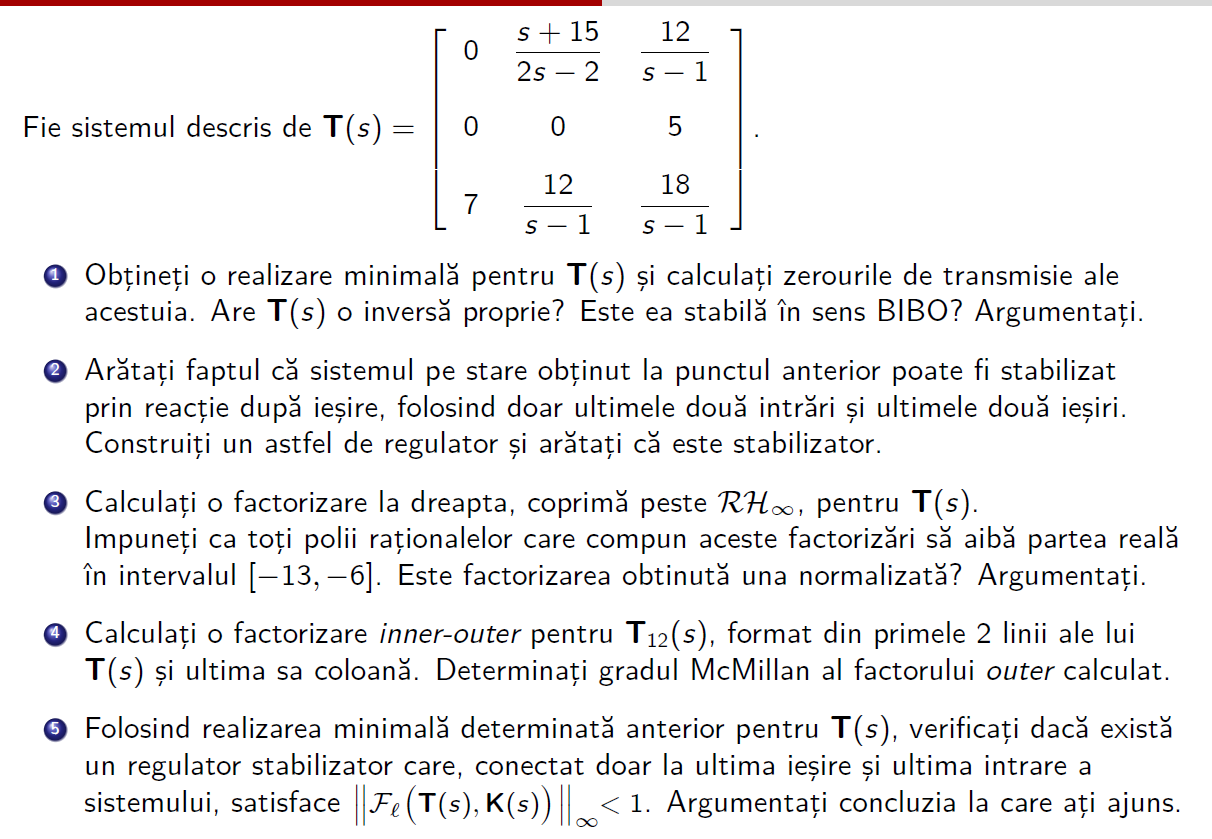

## Problema 1: realizare minimala, zero de transmisie, insersa proprie, stabil BIBO

clear
close all
clc

s = tf('s');

T = [0 (s + 15) / (2*s - 2) 12 / (s - 1);
     0 0 5;
     7 12 / (s - 1) 18 / (s - 1)]


T =
 
  From input 1 to output...
   1:  0
 
   2:  0
 
   3:  7
 
  From input 2 to output...
       s + 15
   1:  -------
       2 s - 2
 
   2:  0
 
        12
   3:  -----
       s - 1
 
  From input 3 to output...
        12
   1:  -----
       s - 1
 
   2:  5
 
        18
   3:  -----
       s - 1
 
Continuous-time transfer function.



T_ss = ss(T,'min')


T_ss =
 
  A = 
       x1
   x1   1
 
  B = 
          u1     u2     u3
   x1      0  2.219  3.328
 
  C = 
          x1
   y1  3.606
   y2      0
   y3  5.408
 
  D = 
        u1   u2   u3
   y1    0  0.5    0
   y2    0    0    5
   y3    7    0    0
 
Continuous-time state-space model.


Pentru ca am realizare minimala, zerourile de invariata = zero de transmisie

tzero(T)

ans =     1.0000
  -15.0000


Ii pica rangul, deci sistem instabil

syms s_sym

T_ss.D

ans =          0    0.5000         0
         0         0    5.0000
    7.0000         0         0



eye(size(T_ss.D)) / T_ss.D

ans =          0         0    0.1429
    2.0000         0         0
         0    0.2000         0


Vad ca D este inversabil, deci T are inversa proprie

disp('Este sistemul stabil?');

Este sistemul stabil?


disp(eig(T_ss.A))

     1



Bine, am vazut la zerouriile de invarianta/transmisie ca pica rangul, deci instabil

## Problema 2: stabilizare dupa ultimele 2 intrati si ultimele 2 iesiri

T_ss


T_ss =
 
  A = 
       x1
   x1   1
 
  B = 
          u1     u2     u3
   x1      0  2.219  3.328
 
  C = 
          x1
   y1  3.606
   y2      0
   y3  5.408
 
  D = 
        u1   u2   u3
   y1    0  0.5    0
   y2    0    0    5
   y3    7    0    0
 
Continuous-time state-space model.


T_mat_ss = [T_ss.A, T_ss.B;
            T_ss.C, T_ss.D]

T_mat_ss =     1.0000         0    2.2188    3.3282
    3.6056         0    0.5000         0
         0         0         0    5.0000
    5.4083    7.0000         0         0


Acum scriem $\left(A,B_2 ,C_2 ,D_2 \right)$

A2 = T_ss.A

A2 = 1


B2 = T_ss.B(:,2:3)

B2 =     2.2188    3.3282



C2 = T_ss.C(2:3,:)

C2 =          0
    5.4083



D2 = T_ss.D(2:3,2:3)

D2 =      0     5
     0     0



T22 = ss(A2, B2, C2, D2)


T22 =
 
  A = 
       x1
   x1   1
 
  B = 
          u1     u2
   x1  2.219  3.328
 
  C = 
          x1
   y1      0
   y2  5.408
 
  D = 
       u1  u2
   y1   0   5
   y2   0   0
 
Continuous-time state-space model.


Pc2 = ctrb(A2, B2)

Pc2 =     2.2188    3.3282


Po2 = obsv(A2, C2)

Po2 =          0
    5.4083



disp('Rangul matricii de controlabilitate:');

Rangul matricii de controlabilitate:


disp(rank(Pc2));

     1



disp('Rangul matricii de observabilitate:');

Rangul matricii de observabilitate:


disp(rank(Po2));

     1



Doamne ajuta, sistem minimal. Deci pot sa stabilizez sistemul T dupa $T_{22}$

Hai sa vedem ca $T_{22}$ ia valorile instabile din T

disp('Valorile proprii din T_ss')

Valorile proprii din T_ss


eig(T_ss)

ans = 1


disp('Valorile proprii din T22')

Valorile proprii din T22


eig(T22)

ans = 1

Vedem ca sistemul format din ultimele 2 intrati si 2 iesiri mosteneste valorile proprii ale intregului sistem

O sa iau K fix compensatorul Kalman (ca ala stiu ca face treaba)

poli_dreapta = -10;
poli_stanga = -11;

F2 = -place(A2, B2, poli_stanga)

F2 =    -1.6641
   -2.4962



L2 = -place(A2', C2', poli_dreapta)'

L2 =          0   -2.0339



disp('Valorile proprii ale lui A+BF');

Valorile proprii ale lui A+BF


disp(eig(A2 + B2 * F2))

  -11.0000




disp('Valorile proprii ale lui A+LC');

Valorile proprii ale lui A+LC


disp(eig(A2 + L2 * C2));

   -10



De la TSA:


$$K\left(s\right)=\left\lbrack \begin{array}{cc}
A+\mathrm{BF}+LC+\mathrm{LDF} & -L\\
F & 0
\end{array}\right\rbrack ,\mathrm{unde}\;\left\lbrace \begin{array}{l}
\Lambda \left(A+\mathrm{BF}\right)\subset {\mathbb{C}}^- \\
\Lambda \left(A+\mathrm{LC}\right)\subset {\mathbb{C}}^- 
\end{array}\right.$$


K = ss(A2 + B2*F2 + L2*C2 + L2*D2*F2, -L2, ...
    F2,zeros(2,2))


K =
 
  A = 
        x1
   x1  -22
 
  B = 
          u1     u2
   x1      0  2.034
 
  C = 
           x1
   y1  -1.664
   y2  -2.496
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



T22_cl = feedback(T22, -K)


T22_cl =
 
  A = 
        x1   x2
   x1    1  -12
   x2   11  -22
 
  B = 
          u1     u2
   x1  2.219  3.328
   x2      0      0
 
  C = 
           x1      x2
   y1       0  -12.48
   y2   5.408       0
 
  D = 
       u1  u2
   y1   0   5
   y2   0   0
 
Continuous-time state-space model.



disp('Valorile proprii ale sistemului T22_cl in bucla inchisa:');

Valorile proprii ale sistemului T22_cl in bucla inchisa:


disp(pole(T22_cl));

  -10.0000
  -11.0000



Acum verific pentru tot sistemul ca sa vedem ca am facut bine

Pun 0 ala ca sa nu afeceteze alte tampenii

K_complet = blkdiag(ss(0),K) 


K_complet =
 
  A = 
        x1
   x1  -22
 
  B = 
          u1     u2     u3
   x1      0      0  2.034
 
  C = 
           x1
   y1       0
   y2  -1.664
   y3  -2.496
 
  D = 
       u1  u2  u3
   y1   0   0   0
   y2   0   0   0
   y3   0   0   0
 
Continuous-time state-space model.



T_cl = feedback(T_ss, -K_complet) % Reactie pozitiva


T_cl =
 
  A = 
        x1   x2
   x1    1  -12
   x2   11  -22
 
  B = 
          u1     u2     u3
   x1      0  2.219  3.328
   x2  14.24      0      0
 
  C = 
            x1       x2
   y1    3.606  -0.8321
   y2        0   -12.48
   y3    5.408        0
 
  D = 
        u1   u2   u3
   y1    0  0.5    0
   y2    0    0    5
   y3    7    0    0
 
Continuous-time state-space model.


% Aici mereu uitam sa pun - ala

Aici ma uit la poli

disp('Valorile proprii ale sistemului in bucla inchisa:');

Valorile proprii ale sistemului in bucla inchisa:


disp(pole(T_cl));

  -10.0000
  -11.0000




if all(real(pole(T_cl)) < 0)
    disp('Sistemul a fost stabilizat cu succes!');
end

Sistemul a fost stabilizat cu succes!


## Problema 3: factorizare coprima la dreapta stabila

Am sistem minimal. In acest sens, fie $F\;\mathrm{si}\;L$ astfel incat $\left\lbrace \begin{array}{l}
\Lambda \left(A+\mathrm{BF}\right)\in {\mathbb{C}}_- \\
\Lambda \left(A+\mathrm{LC}\right)\in {\mathbb{C}}_- 
\end{array}\right.$. Atunci $\left\lbrace \begin{array}{l}
\left\lbrack \begin{array}{cc}
M & X\\
N & Y
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
A+\mathrm{BF} & B & -L\\
F & I & 0\\
C+\mathrm{DF} & 0 & I
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{cc}
\tilde{Y}  & -\tilde{X} \\
-\tilde{N}  & \tilde{M} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
A+\mathrm{LC} & -\left(B+\mathrm{LD}\right) & L\\
F & I & 0\\
C & -D & I
\end{array}\right\rbrack 
\end{array}\right.$

poli_F = -9;
poli_L = -11;

F = -place(T_ss.A, T_ss.B, poli_F)

F =          0
   -1.3868
   -2.0801



L = -place(T_ss.A', T_ss.C', poli_L)'

L =    -1.0241         0   -1.5361


Sa vedem daca merge

disp('Valorile proprii ale lui A+BF');

Valorile proprii ale lui A+BF


disp(eig(T_ss.A + T_ss.B * F))

   -9.0000




disp('Valorile proprii ale lui A+LC');

Valorile proprii ale lui A+LC


disp(eig(T_ss.A + L * T_ss.C));

  -11.0000



Acum facem $M,N,\tilde{M} ,\tilde{N}$

NeTilda

M = ss(T_ss.A + T_ss.B * F, T_ss.B, F, eye(3,3))


M =
 
  A = 
       x1
   x1  -9
 
  B = 
          u1     u2     u3
   x1      0  2.219  3.328
 
  C = 
           x1
   y1       0
   y2  -1.387
   y3   -2.08
 
  D = 
       u1  u2  u3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
 
Continuous-time state-space model.


N = ss(T_ss.A + T_ss.B * F, T_ss.B, T_ss.C + T_ss.D * F, T_ss.D)


N =
 
  A = 
       x1
   x1  -9
 
  B = 
          u1     u2     u3
   x1      0  2.219  3.328
 
  C = 
          x1
   y1  2.912
   y2  -10.4
   y3  5.408
 
  D = 
        u1   u2   u3
   y1    0  0.5    0
   y2    0    0    5
   y3    7    0    0
 
Continuous-time state-space model.


Tilda

Mtilde = ss(T_ss.A + L * T_ss.C, L, T_ss.C, eye(3,3))


Mtilde =
 
  A = 
        x1
   x1  -11
 
  B = 
           u1      u2      u3
   x1  -1.024       0  -1.536
 
  C = 
          x1
   y1  3.606
   y2      0
   y3  5.408
 
  D = 
       u1  u2  u3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
 
Continuous-time state-space model.


Ntilde = ss(T_ss.A + L * T_ss.C, -(T_ss.B + L * T_ss.D), ...
    T_ss.C, -T_ss.D)


Ntilde =
 
  A = 
        x1
   x1  -11
 
  B = 
           u1      u2      u3
   x1   10.75  -1.707  -3.328
 
  C = 
          x1
   y1  3.606
   y2      0
   y3  5.408
 
  D = 
         u1    u2    u3
   y1     0  -0.5     0
   y2     0     0    -5
   y3    -7     0     0
 
Continuous-time state-space model.



Ntilde = -Ntilde


Ntilde =
 
  A = 
        x1
   x1  -11
 
  B = 
           u1      u2      u3
   x1   10.75  -1.707  -3.328
 
  C = 
           x1
   y1  -3.606
   y2       0
   y3  -5.408
 
  D = 
        u1   u2   u3
   y1    0  0.5    0
   y2    0    0    5
   y3    7    0    0
 
Continuous-time state-space model.


Ma pot uita la $G*M-N$ si $\tilde{M} *G-\tilde{N}$ pentru a vedea daca chiar este coprima factorizarea $G={\mathrm{NM}}^{-1} ={\tilde{M} }^{-1} \tilde{\;N}$ 

disp('Ne uitam mai intai in partea dreapta')

Ne uitam mai intai in partea dreapta


norm(T_ss * M - N, 'inf')

ans = 3.1611e-15


disp('Acum sa vedem partea stanga')

Acum sa vedem partea stanga


norm(Mtilde * T_ss - Ntilde, 'inf')

ans = 2.9221e-15

Fie G un sistem aleator. O factorizare coprima la $\left\lbrace \begin{array}{l}
\mathrm{dreapta}:G={\mathrm{NM}}^{-1} \\
\mathrm{stanga}:G={\tilde{M} }^{-1} \tilde{N} 
\end{array}\right.$ se numeste in plus normalizata daca satisface $\left\lbrace \begin{array}{l}
N^{\tilde{} } N+M^{\tilde{} } M=I\\
\tilde{N} {\tilde{N} }^{\tilde{} } +\tilde{M} {\tilde{M} }^{\tilde{} } =I
\end{array}\right.$. Scris in froma matriceala: $\left\lbrace \begin{array}{l}
{\left\lbrack \begin{array}{c}
N\\
M
\end{array}\right\rbrack }^{\tilde{} } \left\lbrack \begin{array}{c}
N\\
M
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
N^{\tilde{} }  & M^{\tilde{} } 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
N\\
M
\end{array}\right\rbrack =I\\
\left\lbrack \begin{array}{cc}
\tilde{N}  & \tilde{N} 
\end{array}\right\rbrack {\left\lbrack \begin{array}{cc}
\tilde{N}  & \tilde{M} 
\end{array}\right\rbrack }^{\tilde{} } =I
\end{array}\right.$

Nu pare a fi normalizata

norm(N'*N+M'*M - eye(3), 'inf')

ans = 54.9706

F si L au fost luati astfel incat polii sa respecte intervalul ala, deci intr-un fel am luat aleator. Erau sanse mici sa dea normalizat

## Problema 4: inner-outer si grad McMillan

T12 = T(1:2,end)


T12 =
 
  From input to output...
        12
   1:  -----
       s - 1
 
   2:  5
 
Continuous-time transfer function.


T12_ss = ss(T12, 'min')


T12_ss =
 
  A = 
       x1
   x1   1
 
  B = 
       u1
   x1   4
 
  C = 
       x1
   y1   3
   y2   0
 
  D = 
       u1
   y1   0
   y2   5
 
Continuous-time state-space model.


Fie $G\left(s\right)=\left\lbrack \begin{array}{cc}
A & B\\
C & D
\end{array}\right\rbrack ,\mathrm{cu}\;\left\lbrace \begin{array}{l}
\left(A,B\right)\;\mathrm{stabilizabil}\\
\left(C,A\right)\;\mathrm{detectabil}
\end{array}\right.\ldotp$ In acest sens, fie $F\;\mathrm{si}\;L$ astfel incat $\left\lbrace \begin{array}{l}
\Lambda \left(A+\mathrm{BF}\right)\in {\mathbb{C}}_- \\
\Lambda \left(A+\mathrm{LC}\right)\in {\mathbb{C}}_- 
\end{array}\right.$. Atunci $\left\lbrace \begin{array}{l}
\left\lbrack \begin{array}{cc}
M & X\\
N & Y
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
A+\mathrm{BF} & B & -L\\
F & I & 0\\
C+\mathrm{DF} & 0 & I
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{cc}
\tilde{Y}  & -\tilde{X} \\
-\tilde{N}  & \tilde{M} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
A+\mathrm{LC} & -\left(B+\mathrm{LD}\right) & L\\
F & I & 0\\
C & -D & I
\end{array}\right\rbrack 
\end{array}\right.$

. Atunci J va avea forma $J=\left\lbrack \begin{array}{ccc}
A+\mathrm{BF}+\mathrm{LC}+\mathrm{LDF} & -L & B+\mathrm{LD}\\
F & 0 & I\\
-\left(C+\mathrm{DF}\right) & I & -D
\end{array}\right\rbrack$

F = -acker(T12_ss.A,T12_ss.B,[-4])

F = -1.2500

eig(T12_ss.A + T12_ss.B * F)

ans = -4

L = -place(T12_ss.A', T12_ss.C', [-4])'

L =    -1.6667         0


eig(T12_ss.A + L * T12_ss.C)

ans = -4

M = ss(T12_ss.A + T12_ss.B * F, T12_ss.B, F, 1)


M =
 
  A = 
       x1
   x1  -4
 
  B = 
       u1
   x1   4
 
  C = 
          x1
   y1  -1.25
 
  D = 
       u1
   y1   1
 
Continuous-time state-space model.


N = ss(T12_ss.A + T12_ss.B * F, T12_ss.B, T12_ss.C + T12_ss.D * F, T12_ss.D)


N =
 
  A = 
       x1
   x1  -4
 
  B = 
       u1
   x1   4
 
  C = 
          x1
   y1      3
   y2  -6.25
 
  D = 
       u1
   y1   0
   y2   5
 
Continuous-time state-space model.


col_rf = [M;
          N];

col_rf = ss(col_rf, 'min')


col_rf =
 
  A = 
       x1
   x1  -4
 
  B = 
          u1
   x1  5.657
 
  C = 
            x1
   y1  -0.8839
   y2    2.121
   y3   -4.419
 
  D = 
       u1
   y1   1
   y2   0
   y3   5
 
Continuous-time state-space model.


Cum am zis trebuie sa facem realizare minimala

 Daca avem $\left\lbrace \begin{array}{l}
\left(A,B\right)\;\mathrm{staebilizabil}\\
\left(C,A\right){\;\mathbb{C}}_0 -\mathrm{observabil}
\end{array}\right.$, atunci:

- Pentru tripletul Popov $\Sigma =\left(A;B;\left\lbrack \begin{array}{cc}
C^T C & C^T D\\
D^T C & D^T D
\end{array}\right\rbrack \right)$ are o solutie stabilizatoare X si reactie stabilizatoare F

- Presupunem $H\in {\mathbb{R}}^{m\times m}$ o **matrice inversabila** astfel incat $H^T H=D^T D$. Facem svd pe D si obtinem: $\mathrm{svd}\left(D\right)=U\left\lbrack \begin{array}{c}
\Sigma \\
0
\end{array}\right\rbrack V^T$. Acum facem $\mathrm{svd}\left(D^T D\right)=V\Sigma^2 V^T$. H o sa il presupunem choeslky din $D^T D$ *(INFERIOR TRIUNGHIULAR)*. Vom defiini: $\left\lbrace \begin{array}{l}
G_o \left(s\right)=\left\lbrack \begin{array}{cc}
A & B\\
-\mathrm{HF} & H
\end{array}\right\rbrack \\
G_i \left(s\right)=\left\lbrack \begin{array}{cc}
A+\mathrm{BF} & {\mathrm{BH}}^{-1} \\
C+\mathrm{DF} & {\mathrm{DH}}^{-1} 
\end{array}\right\rbrack ,A+\mathrm{BF}\;\mathrm{este}\;\mathrm{tot}\;\mathrm{aia}\;\mathrm{cu}\;A-\mathrm{BK},\mathrm{unde}\;F=-K\;\left(\mathrm{curs}\;\mathrm{de}\;\mathrm{CO}\right)
\end{array}\right.$

col_rf.D

ans =      1
     0
     5


rank(col_rf.D) % rand interg

ans = 1

tzero(col_rf) % nu pica rangul, deci este ok


ans =

  0×1 empty double column vector



ACum vedem $\mathrm{EMAR}\left(\Sigma \right)$


$$\Sigma_{\mathrm{io}} :=\left(A;B;P\right)=\left(A;B;Q,L,R\right),\left\lbrack \begin{array}{cc}
Q & L\\
L^T  & R
\end{array}\right\rbrack =P=P^T$$


$Q=C^T C$, $L=C^T D$, $R=D^T D$

[X_r,F_r, spectru_r] = icare(col_rf.A, col_rf.B, col_rf.C'*col_rf.C, col_rf.D'*col_rf.D, col_rf.C'*col_rf.D)

X_r = 2.8901

F_r = -0.2551

spectru_r = -2.5570

F_r = -F_r;
H = chol(col_rf.D'*col_rf.D, 'lower')'

H = 5.0990

T_o = ss(col_rf.A, col_rf.B, -H*F_r, H)


T_o =
 
  A = 
       x1
   x1  -4
 
  B = 
          u1
   x1  5.657
 
  C = 
           x1
   y1  -1.301
 
  D = 
          u1
   y1  5.099
 
Continuous-time state-space model.


Acum pregatec partile pentru $G_{\mathrm{i1}} \;\mathrm{si}\;G_{\mathrm{i2}}$, mai specific $C_{\mathrm{r1}} ,C_{\mathrm{r2}} ,D_{\mathrm{r1}} ,D_{\mathrm{r2}}$

Ideea de baza: stim ca $G_i =\left\lbrack \begin{array}{cc}
A+\mathrm{BF} & {\mathrm{BH}}^{-1} \\
C+\mathrm{DF} & {\mathrm{DH}}^{-1} 
\end{array}\right\rbrack$. Insa noi am scris $G_i =\left\lbrack \begin{array}{c}
G_{\mathrm{i1}} \\
G_{12} 
\end{array}\right\rbrack$. A si B din $G_i$ nu ne afecteaza, ci C si D. Asadar, rescriem: $\left\lbrack \begin{array}{c}
G_{\mathrm{i1}} \\
G_{12} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
A+\mathrm{BF} & {\mathrm{BH}}^{-1} \\
C_1 +D_1 F & D_1 H^{-1} \\
C_2 +D_2 F & D_2 H^{-1} 
\end{array}\right\rbrack$

C_r1 = col_rf.C(1,:) 

C_r1 = -0.8839

C_r2 = col_rf.C(2:3,:)

C_r2 =     2.1213
   -4.4194


D_r1 = col_rf.D(1,:)

D_r1 = 1

D_r2 = col_rf.D(2:3,:)

D_r2 =      0
     5


T_i1 = ss(col_rf.A + col_rf.B * F_r, col_rf.B * eye(size(H)) / H, C_r1 + D_r1 * F_r, D_r1 * eye(size(H)) / H)


T_i1 =
 
  A = 
           x1
   x1  -2.557
 
  B = 
          u1
   x1  1.109
 
  C = 
            x1
   y1  -0.6288
 
  D = 
           u1
   y1  0.1961
 
Continuous-time state-space model.


size(M) % Am atasat dimensiunile pentru a vedea de ce am luat pentru T_i1 si T_i2 C si D asa

State-space model with 1 outputs, 1 inputs, and 1 states.


size(T_i1)

State-space model with 1 outputs, 1 inputs, and 1 states.


T_i2 = ss(col_rf.A + col_rf.B * F_r, col_rf.B * eye(size(H)) / H, C_r2 + D_r2 * F_r, D_r2 * eye(size(H)) / H)


T_i2 =
 
  A = 
           x1
   x1  -2.557
 
  B = 
          u1
   x1  1.109
 
  C = 
           x1
   y1   2.121
   y2  -3.144
 
  D = 
           u1
   y1       0
   y2  0.9806
 
Continuous-time state-space model.


size(N) % Am atasat dimensiunile pentru a vedea de ce am luat pentru G_i1 si G_i2 C si D asa

State-space model with 2 outputs, 1 inputs, and 1 states.


size(T_i2)

State-space model with 2 outputs, 1 inputs, and 1 states.


Verificam acum daca esre norma la dreapta

norm(T_i2 - T12_ss * T_i1, 'inf')

ans = 7.1143e-16

Este $T_o$ al nostru outer?

eig(T_o)

ans = -4

eig(eye(size(T_o)) / T_o)

ans = -2.5570

Acum verific ca $\left\lbrack \begin{array}{c}
\hat{M} \\
\hat{N} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
M\\
N
\end{array}\right\rbrack G_o =\left\lbrack \begin{array}{c}
G_{\mathrm{i1}} \\
G_{\mathrm{i2}} 
\end{array}\right\rbrack G_o$ (verifica si daca este normalizata)

norm(col_rf-[T_i1;T_i2]*T_o, 'inf')

ans = 9.3919e-16

Noi stim ca $T_o$ este scris in realizare minimala si ca $T_o$ este proprie, deci **gradul McMillan coincide cu dimensiunea realizarii minimale. **

tf(T_o) % proprie


ans =
 
  5.099 s + 13.04
  ---------------
       s + 4
 
Continuous-time transfer function.


size(T_o.A,1) % cred ca asta ar fi gradul McMillan

ans = 1